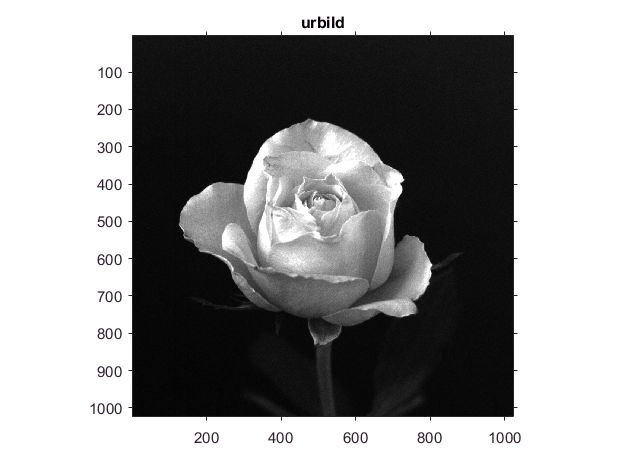

bild=im2double(imread('rose.tif'));

imshow(bild);
title('urbild'); figure;

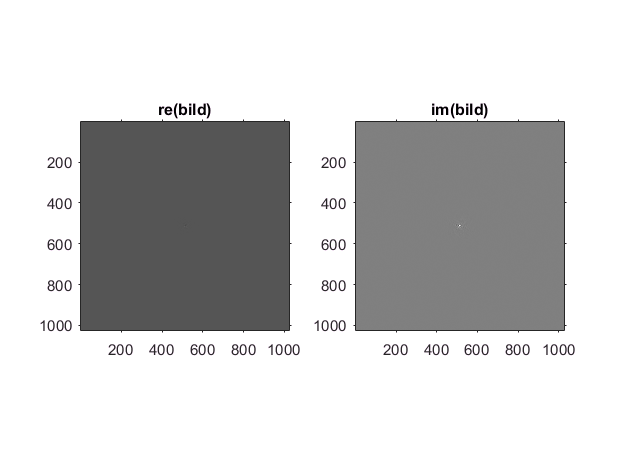


[H, B]=size(bild);
fourier=centerImage(fft2(bild)/numel(bild));

imshowCompl(fourier);

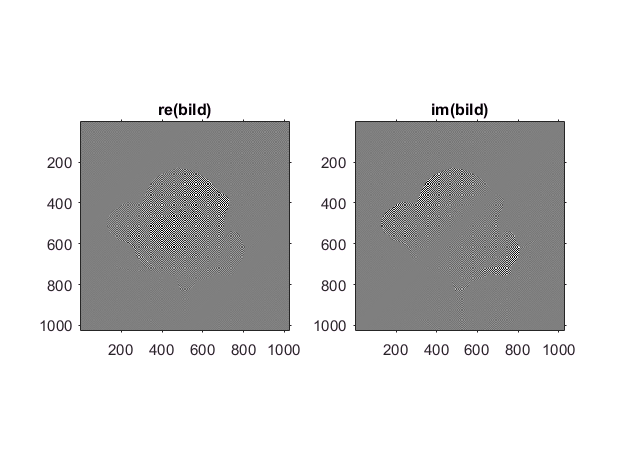


wert=100;
for j=wert:(H-wert)
    for k=wert:(B-wert)
        if j*j+k*k <= wert
            fourier(j, k)=0;
        end
    end
end

Ifourier = ifft2(fourier);

imshowCompl(Ifourier);

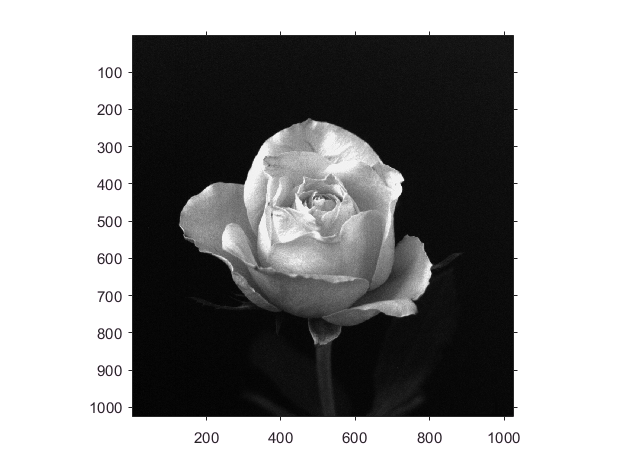


imshow(abs(Ifourier),[]);


size(bild)

ans =         1024        1024


size(Ifourier)

ans =         1025        1025


unterschied = bild - Ifourier;

Error using  - 
Matrix dimensions must agree.


imshow(unterschied, []);